clc;
%part a (Freudenstein's)
%fixed = input('Input the length of the fixed link: ');
fixed = 400

fixed = 400

theta_2 = [];
theta_4 = [];
%theta_not = input('Input the starting range of theta 2: ');
theta_not = 15

theta_not = 15

%theta_f = input('Input the final value of the range of theta 2: ');
theta_f = 165

theta_f = 165

%n = input('Input the number of precision points: ');
n = 3

n = 3

j = 1;
while (j < 4)
    precision_2 = 0.5*(theta_not+theta_f)- 0.5*(theta_f-theta_not)*cosd(180*(2*(j)-1)/(2*n));
    precision_4 = (precision_2)*0.43 +65;
    theta_2 = [theta_2, precision_2];
    theta_4 = [theta_4, precision_4 ];
    j = j+1;
end

A = [cosd(theta_4(1,1)), -cosd(theta_2(1,1)), 1 ; cosd(theta_4(1,2)), -cosd(theta_2(1,2)), 1 ; cosd(theta_4(1,3)), -cosd(theta_2(1,3)), 1];
B = [cosd(theta_2(1,1) - theta_4(1,1)) ; cosd(theta_2(1,2) - theta_4(1,2)) ; cosd(theta_2(1,3) - theta_4(1,3)) ];
sol = linsolve(A,B);

K1 = sol(1,1);
K2 = sol(2,1);
K3 = sol(3,1);

fprintf('K1 = %.15g\n',K1);

K1 = -7.10033346416303


fprintf('K2 = %.15g\n',K2);

K2 = -3.40905521256344


fprintf('K3 = %.15g\n',K3);

K3 = -0.710080694102399



crank_length = fixed /K1;
follower_length = fixed / K2;
coupler_length = sqrt((crank_length*crank_length)+(follower_length*follower_length)+(fixed*fixed)-(K3*2*crank_length*follower_length));

fprintf('crank_length = %.15g\n',crank_length);

crank_length = -56.3353822773098


fprintf('follower_length = %.15g\n',follower_length);

follower_length = -117.334561941348


fprintf('coupler_length = %.15g\n',coupler_length);

coupler_length = 431.657810797272



%transmssion_angle;
theta = 15 :5 :165;
transmission_angle = acosd(((coupler_length^2)+(follower_length^2)-(crank_length^2)-(fixed^2)+(2*crank_length*fixed*cosd(theta)))/(2*coupler_length*follower_length));
disp(' ')

disp('TABLE OF ANGULAR INPUT AND TRANSMISSION ANGLES')

TABLE OF ANGULAR INPUT AND TRANSMISSION ANGLES


disp('   input    transmission   ')

   input    transmission   


disp([theta',transmission_angle'])

   15.0000   86.2583
   20.0000   86.9282
   25.0000   87.7802
   30.0000   88.8075
   35.0000   90.0025
   40.0000   91.3564
   45.0000   92.8599
   50.0000   94.5029
   55.0000   96.2752
   60.0000   98.1658
   65.0000  100.1640
   70.0000  102.2587
   75.0000  104.4386
   80.0000  106.6926
   85.0000  109.0091
   90.0000  111.3765
   95.0000  113.7829
  100.0000  116.2158
  105.0000  118.6624
  110.0000  121.1088
  115.0000  123.5403
  120.0000  125.9410
  125.0000  128.2933
  130.0000  130.5778
  135.0000  132.7731
  140.0000  134.8553
  145.0000  136.7982
  150.0000  138.5732
  155.0000  140.1499
  160.0000  141.4972
  165.0000  142.5844



subplot(2,1,1),plot(theta,transmission_angle),xlabel('\theta(degrees)'),ylabel('transmission angle'),title('transmission angle vs \theta'),grid on
plot(theta, transmission_angle)
output = 65 + 0.43*theta;


%structural error part a)
structural_error = K1*cosd(output)- K2*cosd(theta)+K3-cosd(theta - output);
disp(structural_error)

  Columns 1 through 13

   -0.2287   -0.1048   -0.0009    0.0835    0.1491    0.1970    0.2282    0.2439    0.2456    0.2346    0.2127    0.1815    0.1428

  Columns 14 through 26

    0.0983    0.0501   -0.0000   -0.0501   -0.0982   -0.1425   -0.1810   -0.2119   -0.2336   -0.2443   -0.2425   -0.2267   -0.1955

  Columns 27 through 31

   -0.1479   -0.0827    0.0009    0.1036    0.2261



disp('TABLE OF INPUT ANGLES AND STRUCTURAL ERRORS')

TABLE OF INPUT ANGLES AND STRUCTURAL ERRORS


disp('   input    error   ')

   input    error   


disp([theta',structural_error'])

   15.0000   -0.2287
   20.0000   -0.1048
   25.0000   -0.0009
   30.0000    0.0835
   35.0000    0.1491
   40.0000    0.1970
   45.0000    0.2282
   50.0000    0.2439
   55.0000    0.2456
   60.0000    0.2346
   65.0000    0.2127
   70.0000    0.1815
   75.0000    0.1428
   80.0000    0.0983
   85.0000    0.0501
   90.0000   -0.0000
   95.0000   -0.0501
  100.0000   -0.0982
  105.0000   -0.1425
  110.0000   -0.1810
  115.0000   -0.2119
  120.0000   -0.2336
  125.0000   -0.2443
  130.0000   -0.2425
  135.0000   -0.2267
  140.0000   -0.1955
  145.0000   -0.1479
  150.0000   -0.0827
  155.0000    0.0009
  160.0000    0.1036
  165.0000    0.2261



%subplot(2,1,2),plot(theta,structural_error),xlabel('\theta(degrees)'),ylabel('structural error'),title('structural error vs \theta'),grid on

plot(theta, structural_error)
xlabel('inpout angle')
ylabel("Structural error")
%part b (Least Square)
disp('LEAST   SQUARE')

LEAST   SQUARE


%n5 = input('Input the number of precision points: ');
n5 = 5

n5 = 5

theta_22 = [];
theta_42 = [];
p=1;
while (p < 6)
    precision_22 = 0.5*(theta_not+theta_f)- 0.5*(theta_f-theta_not)*cosd(180*(2*(p)-1)/(2*n5));
    precision_42 = (precision_22)*0.43 +65;
    theta_22 = [theta_22, precision_22];
    theta_42 = [theta_42, precision_42 ];
    p = p+1;
end
ci = cosd(theta_22);
sumci = sum(cosd(theta_22));
co = cosd(theta_42);
sumco = sum(cosd(theta_42));
sumci2 = sum(cosd(theta_22).^2);
sumco2 = sum(cosd(theta_42).^2);
diff = cosd(theta_22-theta_42);
sumd = sum(diff);
e1 =     [
        sumco2,  - sum(co.*ci), sum(co);
        sum(co.*ci), -sumci2, sumci;
        sumco,-sumci,5];
e2 = [sum(co.*diff); sum(ci.*diff); sumd];
als = linsolve(e1,e2);

K1 = als(1);
K2 = als(2);
K3 = als(3);

fprintf('K1 = %.15g\n',K1);

K1 = -1.72930283348068


fprintf('K2 = %.15g\n',K2);

K2 = -0.706090707561717


fprintf('K3 = %.15g\n',K3);

K3 = 0.463202731752506



crank_length = fixed /K1;
follower_length = fixed / K2;
coupler_length = sqrt((crank_length*crank_length)+(follower_length*follower_length)+(fixed*fixed)-(K3*2*crank_length*follower_length));

fprintf('crank_length = %.15g\n',crank_length);

crank_length = -231.307086448759


fprintf('follower_length = %.15g\n',follower_length);

follower_length = -566.499453563531


fprintf('coupler_length = %.15g\n',coupler_length);

coupler_length = 642.676237324018



%structural error part b)
structural_error = K1*cosd(output)- K2*cosd(theta)+K3-cosd(theta - output);
disp('TABLE OF INPUT ANGLES AND STRUCTURAL ERRORS')

TABLE OF INPUT ANGLES AND STRUCTURAL ERRORS


disp('   input    error   ')

   input    error   


disp([theta',structural_error'])

   15.0000    0.0424
   20.0000    0.0450
   25.0000    0.0448
   30.0000    0.0418
   35.0000    0.0363
   40.0000    0.0286
   45.0000    0.0189
   50.0000    0.0076
   55.0000   -0.0050
   60.0000   -0.0186
   65.0000   -0.0327
   70.0000   -0.0471
   75.0000   -0.0614
   80.0000   -0.0750
   85.0000   -0.0876
   90.0000   -0.0988
   95.0000   -0.1082
  100.0000   -0.1153
  105.0000   -0.1198
  110.0000   -0.1213
  115.0000   -0.1194
  120.0000   -0.1138
  125.0000   -0.1041
  130.0000   -0.0900
  135.0000   -0.0713
  140.0000   -0.0477
  145.0000   -0.0190
  150.0000    0.0150
  155.0000    0.0544
  160.0000    0.0994
  165.0000    0.1499



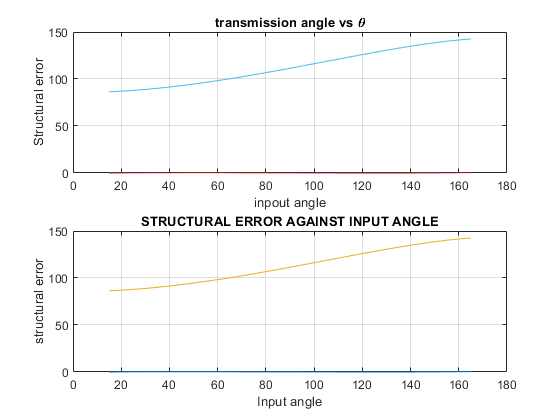

hold all
subplot(2,1,2),plot(theta,structural_error),xlabel('\theta(degrees)'),ylabel('structural error'),title('structural error vs \theta'),grid on
plot(theta, structural_error)
xlabel('Input angle')
ylabel('structural error')
title('STRUCTURAL ERROR AGAINST INPUT ANGLE')